# FFT za pomocą rekurencji

na podstawie indeksu 1a:

N = 1024;
x = rand(1,N);

X = zeros(3,N);

Metoda 1

X(1,:) = DFT(x);

Metoda 2

X1 = DFT( x(1:2:N) );
X2 = DFT( x(2:2:N) );
cX2 = (exp(2*pi*1i/N) .^ (0:N/2-1)).*X2;

% X(2,1:2:N) = X1; X(2,2:2:N) = cX2;
X(2,:) = [ X1 + cX2 , X1 - cX2 ];


Metoda 3

X11 = DFT( x(1:2:N/2) );
X12 = DFT( x(2:2:N/2) );
c1 = (exp(2*pi*1i/(N/2)) .^ (0:N/4-1)).*X12;
X(3,1:N/2) = [ X11 + c1 , X11 - c1 ];

X21 = DFT( x(N/2+1:2:N) );
X22 = DFT( x(N/2+2:2:N) );
c2 = (exp(2*pi*1i/(N/2)) .^ (0:N/4-1)).*X22;
X(3,N/2:N-1) = [ X21 + c2 , X21 - c2 ];


Porownanie danych:

clf
figure
stem(1:N, X(1,:)-X(2,:), 'b')

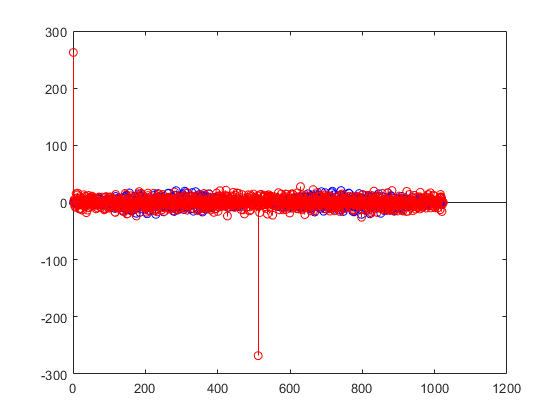

hold on
stem(1:N, X(1,:)-X(3,:), 'r')

function X = DFT(x)
    N = length(x);
    X = zeros(1, N);
    Wn = exp(1i*2*pi/N);
    for k=0:N-1
        for n=0:N-1
            X(k+1)= X(k+1) + x(n+1) * Wn^(-k*n);
        end
    end
    %X = X./N;
end
